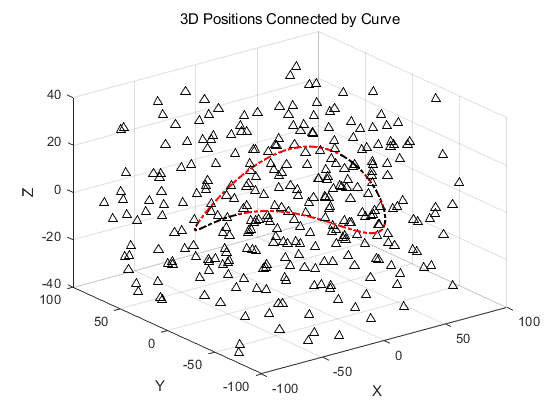

% 假设REKF_result是已经定义好的cell数组
num_elements = numel(REKF_result);
x_coords = [];
y_coords = [];
z_coords = [];

for i = 1:num_elements
    sub_cell = REKF_result{i};
    position = sub_cell.position;
    x_coords = [x_coords; position(1)];
    y_coords = [y_coords; position(2)];
    z_coords = [z_coords; position(3)];
end
figure;
% 使用 plot3 函数绘制三维曲线
plot3(data.poses.position(1,:), data.poses.position(2,:), data.poses.position(3,:), 'r-.',"LineWidth",1.5);hold on;
scatter3( data.landmarks(:, 1), data.landmarks(:, 2), data.landmarks(:, 3), 'k^' ); hold on;plot3(x_coords, y_coords, z_coords, 'k-.',"LineWidth",1.5);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Positions Connected by Curve');
grid on;